ECE 537 

Exercise #5

Group 5

Muqian Gui ----- V00870654

Hang Ruan ----- V00923058

clc;
clear all;
close all;

% Q1
load("Exercise_7_data.mat");

x = data;
y = class';

x_first = x(:, 1);

% Anderson-Darling test
alpha = 0.05;  % Significance level
[h, p, stat] = adtest(x_first, 'Distribution', 'norm', 'Alpha', alpha)

h = logical
   1


p = 5.0000e-04

stat = 132.9818

Based on the Anderson_Darling test results on the first measuremnet feature vector, the p value is very samll and h = 1, this indicate that this feature is not Gaussian distribution.

% Normalize the data first
minValue_all = min(x);
maxValue_all = max(x);
x_normalized = (x - minValue_all) ./ (maxValue_all - minValue_all) * 2 - 1;

% Split data into train and test with balance between each class
trainProportion = 0.25; % 25% of the data for training
% Separate the dataset based on class labels
class0Indices = find(y == 0);
class1Indices = find(y == 1);
% Randomly shuffle the indices for each class
class0ShuffledIndices = class0Indices(randperm(numel(class0Indices)));
class1ShuffledIndices = class1Indices(randperm(numel(class1Indices)));
% Determine the number of samples for each class in the training set
numTrainClass0 = round(trainProportion * numel(class0Indices));
numTrainClass1 = round(trainProportion * numel(class1Indices));
% Split the shuffled indices into training and test indices for each class
trainIndices = [class0ShuffledIndices(1:numTrainClass0); class1ShuffledIndices(1:numTrainClass1)];
testIndices = [class0ShuffledIndices(numTrainClass0+1:end); class1ShuffledIndices(numTrainClass1+1:end)];
% Create the training and test datasets and labels using the indices
x_train = x_normalized(trainIndices, :);
y_train = y(trainIndices);
x_test = x_normalized(testIndices, :);
y_test = y(testIndices);

% Q2 For the first feature
x_train_first = x_train(:,1);
x_test_first = x_test(:,1);

errorRate_1 = GMMerror(y,x_train_first,y_train,x_test_first,y_test,1)

errorRate_1 = 0.0403

% Q3 For the second feature
x_train_second = x_train(:,2);
x_test_second = x_test(:,2);

errorRate_2 = GMMerror(y,x_train_second,y_train,x_test_second,y_test,1)

errorRate_2 = 0.0490

% Q4 For the whole dataset
errorRate_all = GMMerror(y,x_train,y_train,x_test,y_test,1)

errorRate_all = 0.0110

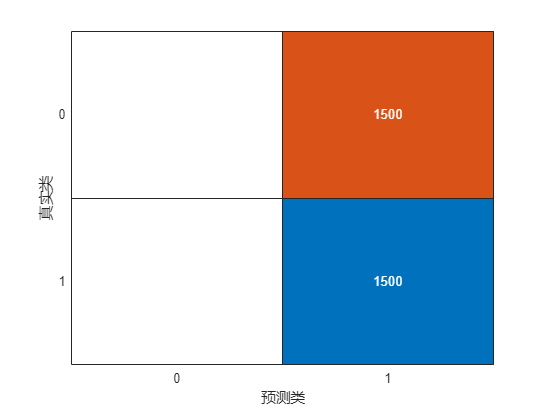

cm_nn =   ConfusionMatrixChart - 属性:

    NormalizedValues: [2×2 double]
         ClassLabels: [2×1 double]

  显示 所有属性


% Q5 Using the Neural Network classifier with patternnet function
% Train the neural network classifier
x = x_train';
t = y_train';
trainFcn = 'trainscg';  % Scaled conjugate gradient backpropagation.
% Create a Pattern Recognition Network
hiddenLayerSize = 10;
net = patternnet(hiddenLayerSize, trainFcn);
net.inputs{1}.processFcns = {};
[net,tr] = train(net,x,t); % Train the Network
y = net(x_test'); % Predicted value from Neuro Network
yind = vec2ind(y); % Round to ind
tind = y_test';

cm_nn = confusionchart(tind', yind')

percentErrors = sum(yind ~= tind)/numel(tind)

percentErrors = 0.5000

Doesn't know somehow the neural network with patternnet function predict all the test data as class 1. As checked the training dataset and test dataset are random split and each class is balanced and with normalization applied on all data. Not sure where the problem is. So try to use the feedforward neural network to train the data and the results shown below.

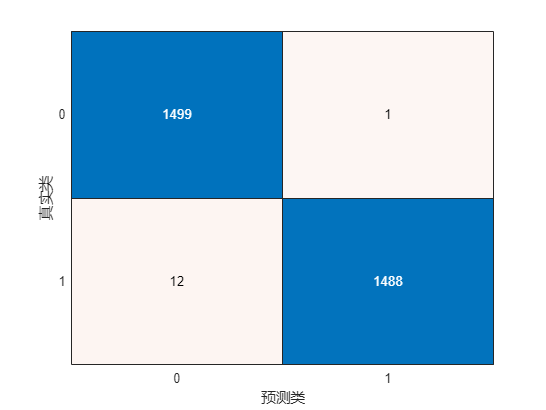

cm_fnn =   ConfusionMatrixChart - 属性:

    NormalizedValues: [2×2 double]
         ClassLabels: [2×1 double]

  显示 所有属性


% With using Feedforward Neural Network
hiddenLayerSize = 10;
net_fnn = feedforwardnet(hiddenLayerSize);
% Train the FNN
net_fnn = train(net_fnn, x_train', y_train');
% Predict on the test set
y_pred = round(net_fnn(x_test'));
% Evaluate the FNN performance
cm_fnn = confusionchart(y_test, y_pred)

percentErrors_fnn = sum(y_pred ~= y_test') / numel(y_test)

percentErrors_fnn = 0.0043

As the results shown here, the error obtained is 0.004 which looks good. But compare with the theorical error obtained from above, this classifier shows little overfitting problem as the theoritical error rate is about 0.01 shown above.

% Q6
corrMatrix = corrcoef(x_normalized)

corrMatrix =     1.0000    0.7493    0.7493   -0.7493    0.0313    0.7423
    0.7493    1.0000    1.0000   -1.0000    0.0169    0.9893
    0.7493    1.0000    1.0000   -1.0000    0.0169    0.9893
   -0.7493   -1.0000   -1.0000    1.0000   -0.0169   -0.9893
    0.0313    0.0169    0.0169   -0.0169    1.0000    0.0178
    0.7423    0.9893    0.9893   -0.9893    0.0178    1.0000


The relationship between each feature can be seen from the correlation matrix. Most features are statiscally depend on each other. As coefficient shows between first feature and feature 2 3 4 6 are about 0.75, this indicate the first feature shows positive linear relationship with feature 2, 3 and 6, negative linear linear relationship with feature 4. But didn't has linear relationship with feature 5. In addition, feature 2 has strong linear relationship with feature 3, 6 and strong negative relationship with feature 4.  Similarly, feature 3 also has a strong relationship with feature 6. Looks like ony feature 5 is independent with other featrues as the coefficient with other features are all close to 0. But this can only indicate the linear relationship. For the value like 0.0313 might have a potentially dependent relationship but just not linear dependence.

Q7

They are both measurements that are use to find the relationships between variables. Statistical correlation measures the linear relationship between each pair feature and often ranges from -1 to 1. Value close to 1 menas strong linear relationship and 0 indicates no linear relationship. Correlation can only capture the linear dependence but not other form dependence. 

Mutual information measure the statistical dependence between two variables. It provides a more comprehensive measure with considering the entir joint distribution and information hsared between features. It able to capture any type of relationship between features like nonlinear or non-monotonic relationships. It provides value from 0 to positive value. 0 means independence between two features and higher value present increasing dependence.

 As correlation can only capture linear dependence, un correlated only means linear indenpendence between features. Features can still share information given they're uncorrelated when there is a non-linear relationship between features.

Q8

Parametric classifier often makes assumption about the underlying distribution for our dataset and independence among features. Correlated features can cause unstable parameter prediction and inaccurate predictions. High mutual information means more similiar information provided which will need more predictive power, this will result some issues like overfitting.  Which potentially leading to biased or unstable model. 

For non-parametric classifiers, highly correlated or mutually informative features might able to provide complementary information, which allow the classifier to capture compex relationships in the data. which potentially increasing the performance. However, on the other hand, highly correlated or mutual information migh also provide more irrelevant information and this will result model being sensitive to the noisy.

Parametric classifiers are more easier to be affected by the highly correlated or mutal information as the classifier make assumption about the underlying distribution. By comparison, non-parametric classifier are less sensitive to correlations between features. They're more flexible and don't make much assumptions about the data distribution. They can utilize redundant information to improve on prediction accuracy. However, they are still sensitive to irrelevant feature which will potentially leading poor performance. Overall, parametric classifier are more sensitive to correlation within features than non-parametric classifier. Non-parametric classifier are more flexible and can handle complex data better. 

Q9

We can identify polynomial relationships using polynomial regression with polynomial terms of higher degrees. Similarly, the non-linear regression model can model non-linear relationships with using non-linear relationship function or transformations.Utilize models like Generalized Additive Models also work. In addition, mutual information can be used to discover any complex relationship involving multiple feature vectors. And also correlation matrix can also provide view on non-linear relationship between each pair feature.

function errorRate = GMMerror(label, train, trainLabel, test, testLabel, numComponents)

numComponents = 1; % Number of Gaussian components in the GMM
gmmClass0 = fitgmdist(train(trainLabel == 0,:), numComponents, 'Regularize', 0.1);
gmmClass1 = fitgmdist(train(trainLabel == 1,:), numComponents, 'Regularize', 0.1);
% Compute class priors
priorClass0 = sum(trainLabel == 0) / numel(label);
priorClass1 = sum(trainLabel == 1) / numel(label);
% Compute class-conditional densities for test samples
pdfClass0 = pdf(gmmClass0, test);
pdfClass1 = pdf(gmmClass1, test);
% Apply the decision rule and assign predicted labels
y_predicted = pdfClass1 > pdfClass0;
% Calculate the Bayes classification error rate
errorRate = sum(y_predicted ~= testLabel) / numel(testLabel);

end
